% Número de repeticiones
N = 1e7;

% Datos aleatorios de entrada
x = rand(N, 1);
k = 0.9;  % parámetro elíptico para funciones de Jacobi

% Lista de operaciones y funciones asociadas
operations = {
    '$2x$',               @() 2*x;
    '$x^2$',              @() x .^ 2;
    '$e^x$',              @() exp(x);
    '$\sin(x)$',          @() sin(x);
    '$\mathrm{sn}(x,k)$', @() ellipj(x, k);
};

% Inicializar tiempos
nOps = size(operations, 1);
times_us = zeros(nOps, 1);

% Medir tiempos
fprintf('Benchmark de operaciones matemáticas:\n');

Benchmark de operaciones matemáticas:


for i = 1:nOps
    name = operations{i, 1};
    func = operations{i, 2};
    tic;
    func();
    t = toc;
    times_us(i) = (t / N) * 1e6;  % Tiempo en microsegundos por operación
    fprintf('%-20s → %.3f μs por operación\n', erase(name, '$'), times_us(i));
end

2x                   → 0.002 μs por operación
x^2                  → 0.002 μs por operación
e^x                  → 0.003 μs por operación
\sin(x)              → 0.002 μs por operación
\mathrm{sn}(x,k)     → 0.986 μs por operación


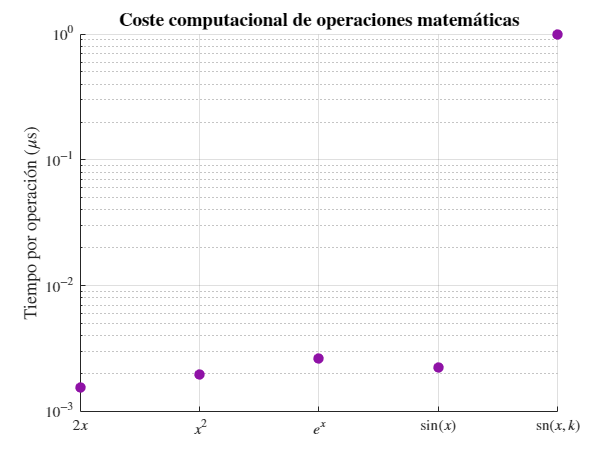


% Gráfica scatter con escala logarítmica en el eje Y
fig = figure;
scatter(1:nOps, times_us, 50, 'filled', 'MarkerFaceColor', [0.56 0.07 0.65]);
set(gca, 'YScale', 'log');  % Escala log en Y
grid on;

% Eje X con etiquetas en LaTeX
xticks(1:nOps);
xticklabels(operations(:,1));
set(gca, 'TickLabelInterpreter', 'latex');

% Eje Y y título con LaTeX
ylabel('Tiempo por operaci\''on ($\mu$s)', 'Interpreter', 'latex', 'FontSize', 12);
title('\textbf{Coste computacional de operaciones matem\''aticas}', 'Interpreter', 'latex', 'FontSize', 13);

% Guardar figura como SVG
saveas(fig, 'benchmark_operaciones.svg');